Autor: Wirley Almeida

15/12/2021

Introdução à Programação com MATLAB

Semana 8

Cells

clear; clc; close all;

cells_of_text


You could find him on the field almost any day.
Tall, dark hair, and eyes of steel gray.
They say he pulled a Frisbee 'bout half a mile,
And when he'd stick in the corner, you could almost catch a smile
On Big Jonh.



whos

  Name      Size            Bytes  Class     Attributes

  ii        1x1                 8  double              
  page      1x5               982  cell                



page{1}

ans = 'You could find him on the field almost any day.'

page{5}

ans = 'On Big Jonh.'

class(page)

ans = 'cell'

class(page{1})

ans = 'char'

size(page{1})

ans =      1    47


class(page{4})

ans = 'char'

size(page{4})

ans =      1    65


p = cell(2,3)

p = 2×3 cell array
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}


p{2,1} = pi

p = 2×3 cell array
    {0×0 double}    {0×0 double}    {0×0 double}
    {[  3.1416]}    {0×0 double}    {0×0 double}


p{1,1} = int8(-17)

p = 2×3 cell array
    {[   -17]}    {0×0 double}    {0×0 double}
    {[3.1416]}    {0×0 double}    {0×0 double}


p{2,2} = 'Awesome'

p = 2×3 cell array
    {[   -17]}    {0×0 double}    {0×0 double}
    {[3.1416]}    {'Awesome' }    {0×0 double}


p{2,3} = [2 4; 6 8; 10 12]

p = 2×3 cell array
    {[   -17]}    {0×0 double}    {0×0 double}
    {[3.1416]}    {'Awesome' }    {3×2 double}


p{1,3} = sum(p{2,3})

p = 2×3 cell array
    {[   -17]}    {0×0 double}    {1×2 double}
    {[3.1416]}    {'Awesome' }    {3×2 double}


p{1,2} = 1/0

p = 2×3 cell array
    {[   -17]}    {[    Inf]}    {1×2 double}
    {[3.1416]}    {'Awesome'}    {3×2 double}


class(p)

ans = 'cell'

class(p{1,2})

ans = 'double'

class(p(1,2))

ans = 'cell'

p{2,3}(3,2)

ans = 12

c{1} = pi

c = 1×2 cell array
    {[3.1416]}    {'Cell or not cell?'}


c{2} = 'Cell or not cell?'

c = 1×2 cell array
    {[3.1416]}    {'Cell or not cell?'}


c

c = 1×2 cell array
    {[3.1416]}    {'Cell or not cell?'}


c{1}

ans = 3.1416

c{2}

ans = 'Cell or not cell?'

c(1)

ans = 1×1 cell array
    {[3.1416]}


c(2)

ans = 1×1 cell array
    {'Cell or not cell?'}


c1 = {[1 2], [10, 20]}

c1 = 1×2 cell array
    {1×2 double}    {1×2 double}


c2 = c1

c2 = 1×2 cell array
    {1×2 double}    {1×2 double}


c1{1,1}

ans =      1     2


c2{1,1}

ans =      1     2


c1{1,2}

ans =     10    20


c2{1,2}

ans =     10    20


c1{1,1} = 'strawberries'

c1 = 1×2 cell array
    {'strawberries'}    {1×2 double}


c2{1,1}

ans =      1     2


c1{1,1}

ans = 'strawberries'

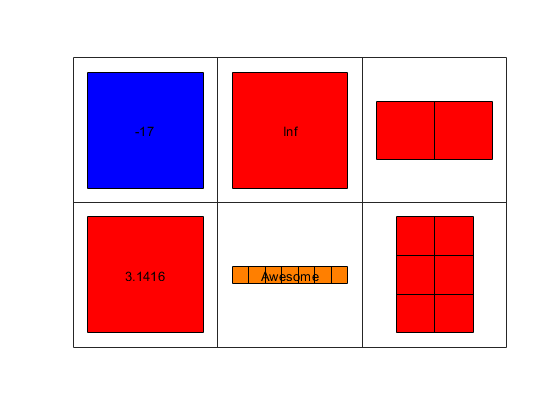

cellplot(p)

iscell(c)

ans = logical
   1


celldisp(p)

 
p{1,1} =
 
   -17

 
 
p{2,1} =
 
    3.1416

 
 
p{1,2} =
 
   Inf

 
 
p{2,2} =
 
Awesome
 
 
p{1,3} =
 
    18    24

 
 
p{2,3} =
 
     2     4
     6     8
    10    12

 
